# Data Fitting

Script Solves for coefficients of production equations and plots the equations on graphs

% Calculates time interval Domain for February, 2013
startIndex=find(date=='01-Feb-2013');  
endIndex=find(date=='01-Mar-2013')-1;

% Values of these vectors will be defined when the main script runs

% Alters various vector values when when turbine2Fuel=0 to increase
% accuracy of coefficients 
for i=1:length(startIndex:endIndex)
    if turbine2Fuel(i)==0
        turbine2Prod(i)=NaN;
        turbine2Fuel(i)=NaN;
        temp(i)=NaN;
        natGasDensity(i)=NaN;
        turbine2CO(i)=NaN;
        turbine2NOx(i)=NaN;
    end
end

% Function solves for coefficients for Prod, CO, and NOx
[Prod_a]=Regression(startIndex,endIndex,turbine2Prod,turbine2Fuel,temp,natGasDensity);

Prod_a =        -148.22
          0.23
          0.28
         -0.00
         -0.00


[CO_a]=Regression(startIndex,endIndex,turbine2CO,turbine2Fuel,temp,natGasDensity);

CO_a =          10.97
         -0.01
         -0.08
          0.00
          0.00


[NOx_a]=Regression(startIndex,endIndex,turbine2NOx,turbine2Fuel,temp,natGasDensity);

NOx_a =           2.52
         -0.00
          0.00
         -0.00
          0.00


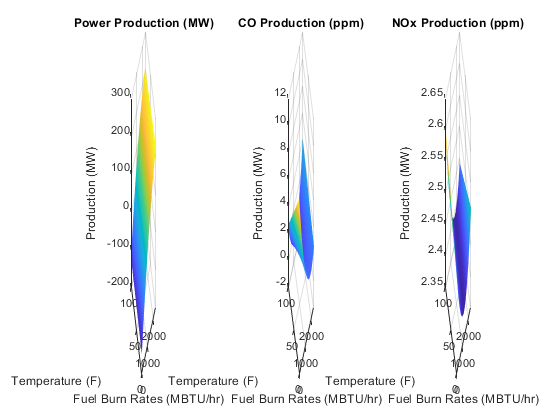


% Indices used in new equations to predict potential production outputs
% for power, CO and NOx
Temp=[0:.1:100]; % (F)
FuelBurn=[0:10:2500]; %MBTU/hr

% Creates empty matricies for expected values 
Power=zeros(length(Temp),length(FuelBurn)); %(MW)
CO=zeros(length(Temp),length(FuelBurn)); %(ppm)
NOx=zeros(length(Temp),length(FuelBurn)); %(ppm)

% Tests all possible Temperature and Fuel Burn combinations to solve for
% predicted production 
for i=1:length(Temp)
    for j=1:length(FuelBurn)
        
        Power(i,j)=Prod_a(1)+Prod_a(2).*FuelBurn(j)+Prod_a(3).*Temp(i)...
            +Prod_a(4).*Temp(i).*FuelBurn(j)+Prod_a(5).*(FuelBurn(j)).^2;
        
        CO(i,j)=CO_a(1)+CO_a(2).*FuelBurn(j)+CO_a(3).*Temp(i)+CO_a(4)...
            .*Temp(i).*FuelBurn(j)+CO_a(5).*(FuelBurn(j)).^2;
        
        NOx(i,j)=NOx_a(1)+NOx_a(2).*FuelBurn(j)+NOx_a(3).*Temp(i)...
            +NOx_a(4).*Temp(i).*FuelBurn(j)+NOx_a(5).*(FuelBurn(j)).^2;  
    end
end

%Plots predicted Production 
figure
subplot(1,3,1)
surf(FuelBurn,Temp,Power) %
title('Power Production (MW)');
xlabel('Fuel Burn Rates (MBTU/hr)');
ylabel('Temperature (F)');
zlabel('Production (MW)');
shading interp

subplot(1,3,2)
surf(FuelBurn,Temp,CO)
title('CO Production (ppm)');
xlabel('Fuel Burn Rates (MBTU/hr)');
ylabel('Temperature (F)');
zlabel('Production (MW)');
shading interp

subplot(1,3,3)
surf(FuelBurn,Temp,NOx)
title('NOx Production (ppm)');
xlabel('Fuel Burn Rates (MBTU/hr)');
ylabel('Temperature (F)');
zlabel('Production (MW)');
shading flat

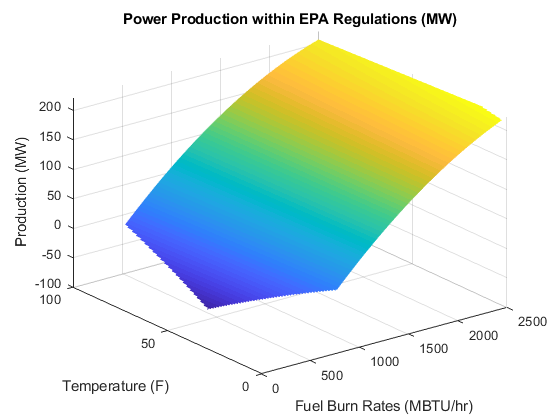


newPower = zeros(length(Temp),length(FuelBurn));

% Finds values of Power within EPA regulations, CO<=5 ppm & NOx<=2.5 ppm
for i=1:length(Temp)
    for j=1:length(FuelBurn)
        if CO(i,j)>5 || NOx(i,j)>2.5
            newPower(i,j)=NaN;
        else
            newPower(i,j)=Power(i,j);
        end
    end
end

% Plots Power within EPA regulations 
figure
surf(FuelBurn,Temp,newPower)
title('Power Production within EPA Regulations (MW)');
xlabel('Fuel Burn Rates (MBTU/hr)');
ylabel('Temperature (F)');
zlabel('Production (MW)');
shading interp  

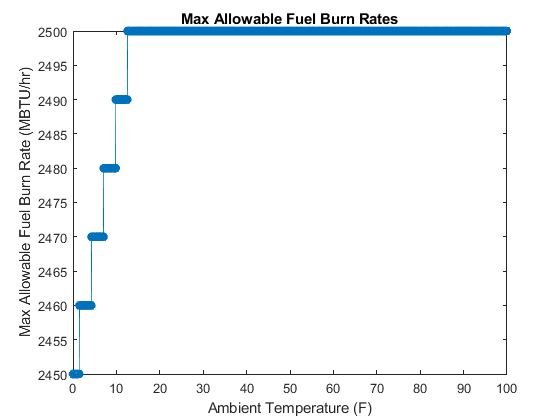


maxAllowableFR = zeros(1,length(Temp));
[x,nP_col] = size(newPower);
max_nP = -10000;
max_j = 1;
% Solves for max allowable Fuel burn rates within EPA regulations 
for i=1:length(Temp)
    for j = 76: nP_col

        nP = newPower(i,j);
        if isnan(nP)
        elseif nP > max_nP
            max_nP = nP;
            max_j = j;        
        end
    
    end
    maxAllowableFR(i)=FuelBurn(max_j);
    max_j=1;
    max_nP = -10000;
end

% Plots Max Allowable Fuel burn rates within EPA regulations
figure
plot(Temp,maxAllowableFR,'-o')
title('Max Allowable Fuel Burn Rates')
xlabel('Ambient Temperature (F)')
ylabel('Max Allowable Fuel Burn Rate (MBTU/hr)')
zlabel('Production (MW)');